dane = audioDatastore("dane\","IncludeSubfolders", true, 'LabelSource','foldernames')

dane =   audioDatastore with properties:

                       Files: {
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00001.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00002.wav'
                               ... and 497 more
                              }
                     Folders: {
                              ' ...\Jakub Poćwiardowski\MATLAB\Projects\BayesMusicClassification\dane'
                              }
                      Labels: [blues; blues; blues ... and 497 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[daneTrain, daneTest] = splitEachLabel(dane,0.8);
[x,xinfo] = read(daneTrain); %przeczytanie pierwszego celem uzyskania informacji do ekstraktora



%%


fs = xinfo.SampleRate;


% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",fs, ...
    "Window",hamming(4096,"periodic"), ...
    "OverlapLength",round(4096*0.5), ...
    "melSpectrum",true,"mfcc",true, ...
    "mfccDelta",true,"mfccDeltaDelta",true, ...
    "gtcc",true,"gtccDelta",true, ...
    "gtccDeltaDelta",true,"spectralCentroid",true, ...
    "pitch",true,"harmonicRatio",true, ...
    "zerocrossrate",true,"shortTimeEnergy",true);
setExtractorParameters(extractor,"mfcc","NumCoeffs",20);

% Extract features from audio data
features = extract(extractor,x);
outputMap = info(extractor)

outputMap = struct with fields:
         melSpectrum: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32]
                mfcc: [33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52]
           mfccDelta: [53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72]
      mfccDeltaDelta: [73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92]
                gtcc: [93 94 95 96 97 98 99 100 101 102 103 104 105]
           gtccDelta: [106 107 108 109 110 111 112 113 114 115 116 117 118]
      gtccDeltaDelta: [119 120 121 122 123 124 125 126 127 128 129 130 131]
    spectralCentroid: 132
               pitch: 133
       harmonicRatio: 134
       zerocrossrate: 135
     shortTimeEnergy: 136



featureMatrix = extract(extractor,x);
[numWindows,numFeatures] = size(featureMatrix)

numWindows = 322

numFeatures = 136

pFlag = ~isempty(ver("parallel"));
daneTrainT = transform(daneTrain,@(x){extract(extractor,x)})

daneTrainT =   TransformedDatastore with properties:

      UnderlyingDatastores: {audioDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@(x){extract(extractor,x)}}
               IncludeInfo: 0


features = readall(daneTrainT,UseParallel=pFlag)

features = 400×1 cell array
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}
    {322×136 double}


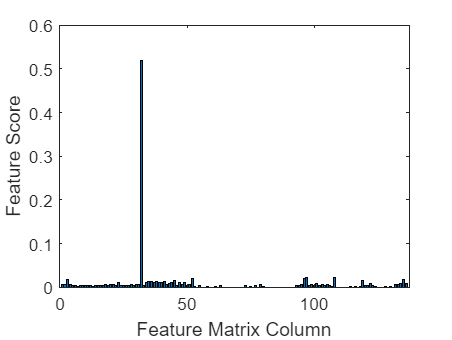

N = cellfun(@(x)size(x,1),features);
T = repelem(daneTrain.Labels,N);
X = cat(1,features{:});
rng("default") % for reproducibility
[featureSelectionIdx,featureSelectionScores] = fscmrmr(X,T);
figure
bar(featureSelectionScores)
ylabel("Feature Score")
xlabel("Feature Matrix Column")

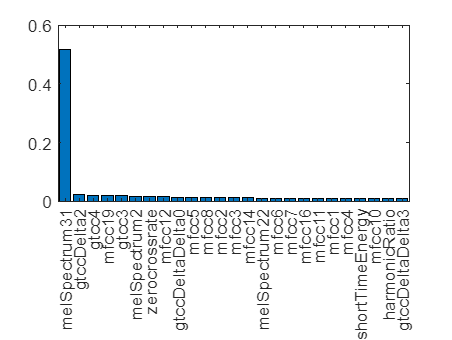

featurenames = uniqueFeatureName(outputMap);

featurenamesSorted = featurenames(featureSelectionIdx);
figure
bar(reordercats(categorical(featurenames),featurenamesSorted),featureSelectionScores)
xlim([featurenamesSorted(1),featurenamesSorted(25)])

selectedFeatureIndex = featureSelectionIdx(1:30);

%Mdl = fitcnb(X(:,selectedFeatureIndex),T)
Mdl = fitcknn(X(:,selectedFeatureIndex),T, Standardize=true, Distance="cosine", NumNeighbors=1)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [blues    classical    metal    pop    reggae]
           ScoreTransform: 'none'
          NumObservations: 128811
                 Distance: 'cosine'
             NumNeighbors: 1


  Properties, Methods


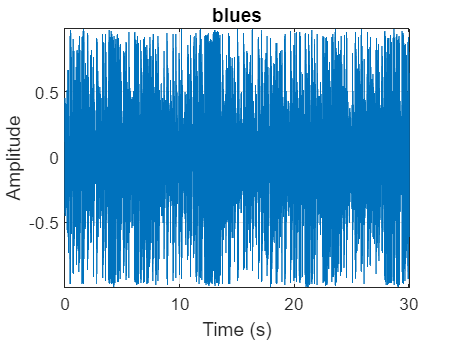

[x,xInfo] = read(daneTest);
%sound(x,xInfo.SampleRate)

t = (0:numel(x)-1)/xInfo.SampleRate;
figure
plot(t,x)
title(xInfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

yPerWindow = extract(extractor,x);
t = predict(Mdl,yPerWindow(:,selectedFeatureIndex));
trueLabel = categorical(xInfo.Label)

trueLabel = categorical
     blues 


predictionsPerWindow = categorical(t')

predictionsPerWindow = 1×322 categorical array
     metal      classical      blues      classical      blues      classical      classical      blues      blues      blues      blues      reggae      reggae      blues      blues      blues      blues      blues      reggae      blues      blues      blues      blues      blues      blues      blues      metal      metal      blues      metal      metal      blues      metal      reggae      reggae      blues      classical      metal      metal      metal      metal      blues      blues      blues      blues      blues      reggae      blues      blues      blues      blues      metal      blues      classical      reggae      reggae      reggae      reggae      classical      blues      metal      metal      blues      reggae      blues      blues      blues      blues      blues      classical      blues      blues      blues      metal      blues      reggae      blues      blues      metal      blues      metal      metal      bl

prediction = mode(predictionsPerWindow) %najwięcej wystąpień

prediction = categorical
     blues 


%dodaj w classifyGenre rozkł. prawdopodobieństw tego

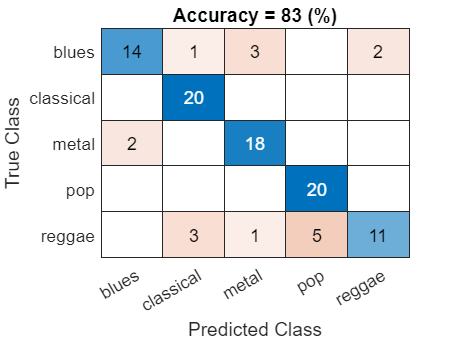

Tfile = categorical(daneTest.Labels);
daneTestT = transform(daneTest,@(x)extract(extractor,x));
daneTestTT = transform(daneTestT,@(x)mode(categorical(predict(Mdl,x(:,selectedFeatureIndex)))));
Y = readall(daneTestTT);
figure
confusionchart(Tfile,Y,Title="Accuracy = " + 100*mean(Tfile==Y) + " (%)")